# MATH2089 Lab 5

In the previos lab we had a brief look at *estimators*—a function of your sample data used to provide an informed estimate of an unknown quantity. These unknown quantities can be generally classed into two categories

- Model parameters: quantities that define the exact type of distribution, e.g., $\lambda$ in the $\text{Exp}(\lambda)$ distribution

- Population parameters: quantities that arise from distributions, e.g., the true population mean $\mu$ for a given distribution $F_{\theta}$

In some cases the model and population parameters coincide, e.g., the mean $\mu$ for the Normal distribution. Similarly to estimators, *sample statistics* are any function of only your sample data—not necessarily used to estimate a model parameter. For example, we might want to compute $T = n^{-1}\sum^{n}_{i = 1} \mathbf{1}\{X_{i} < c\}$—the proportion of a sample $X_{1},\dots,X_{n}$ that is smaller than $c$. The aforementioned statistic $T$ is usually not related to any model parameter, but does provide an estimate for the population parameter $F(c) = \mathbb{P}(X < c)$. Of course in some instances the sample statistic will also be an estimator, e.g., the sample mean is a sample statistic and an estimator for the population and model parameter $\mu$ for the $N(\mu, 1)$ distribution. Note that a statistic cannot include unknown quantities such as unknown model parameters.

In today's lab we'll use statistics to estimate the population mean and proportion—prefacing *population* implies that the quantity is with respect to the true data generating distribution $F$ and not the sample $X_{1},\dots,X_{n}$. As statistics are functions of random variables, the sample statistic is itself also a random variable, and hence has a distribution. The value of the statistic will depend on the sample we obtain, and so it can be overzealous to assume the population parameter is equal to the observe sample statistic. As an example, suppose that the population mean $\mu = 0$. 

rng(11) % set the seed to fix the random number generator

sampleOne = normrnd(0, 1, 5, 1)

sampleOne =    -0.4226
   -1.7742
   -0.0726
    1.1950
   -0.1232


sampleTwo = normrnd(0, 1, 5, 1)

sampleTwo =    -0.0306
   -2.4298
   -0.0565
    0.6516
    1.7254



mean(sampleOne)

ans = -0.2395

mean(sampleTwo)

ans = -0.0280

We see that neither of the sample averages is exactly 0, although the sample average from the second sample is certainly closer. In practice we don't know the value of the population parameter, so we can't determine how close our observed sample statistic is. However, if our sample statistic is unbiased—so that the expected value of the sample statistic is equal to the population paramter—then we can add some margin of error using the distributional properties of the sample statistic to give us a range of plausible values for the population parameter. 

## Exercise 1

In this question we want to estimate the population mean for `shearstrength`. Let's begin as usual by plotting the data. 

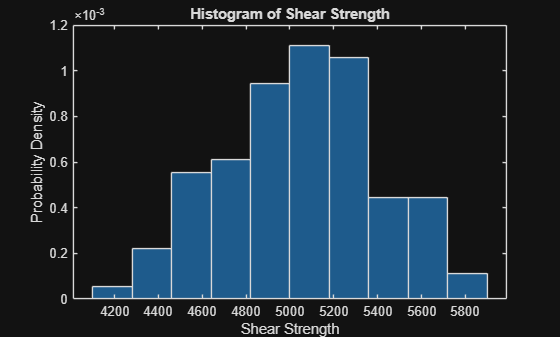

shearstrength = readvars("data\shearstrength.txt");
n = length(shearstrength);
nBins = sqrt(n);

histogram(shearstrength, nBins, "Normalization", "pdf");
xlabel('Shear Strength');
ylabel('Probability Density');
title('Histogram of Shear Strength');

The histogram is bell-shaped, which gives us some indication that `shearstrength` may be Normally distributed. We can get a more precise depiction of the Normality of `shearstrength` through a quantile plot.

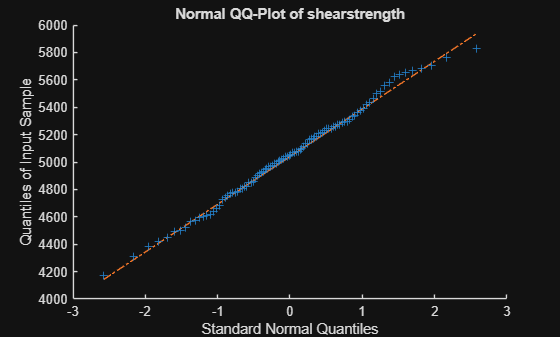

qqplot(shearstrength);
title("Normal QQ-Plot of shearstrength")

Here we can clearly see that the `shearstrength` is Normally distributed since the quantiles of the sample data align closely with the quantiles of a Normal distribution. Based on the quantile plot, we'll make the assumption that `shearstrength` is Normally distributed. In practice you are unlikely to see data sets align exactly with the quantile line—see the example of a precisely Normal data set below. When making an assessment, we try to establish whether the data is globally approximated by the Normal quantiles. You are likely to see some deviation in the tails as these points are inherently more variable.  

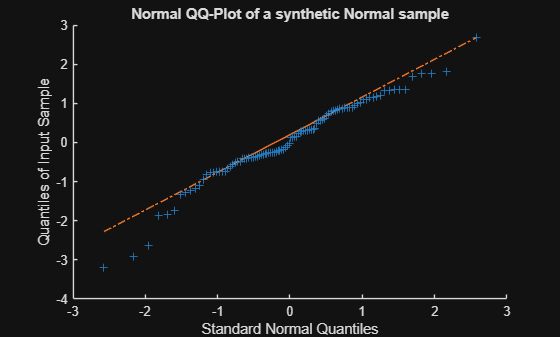

qqplot(normrnd(0, 1, 100, 1));
title("Normal QQ-Plot of a synthetic Normal sample")

Recall that Normally distributed random variables are closed under linear combinations, and in particular, if $X_{1},\dots,X_{n}$ are independently $N(\mu,\sigma)$, then $\sqrt{n}\left(\overline{X} - \mu\right) / \sigma \sim N(0,1)$. The quantity $T = \sqrt{n}\left(\overline{X} - \mu\right) / \sigma$ called a *pivot*, which is a function of the sample data and unknown quantites, but for whom the distribution does not dependent on the unknown quantity. We use the pivot to construct *confidence intervals*. Suppose that we want to find an interval $(a,b)$ such that $\mathbb{P}(a \leq \mu \leq b) \geq 1 - \alpha$, where $\alpha\in (0,1)$. The probability statement wants us to find two points $a$ and $b$ such that $\mu\in (a,b)$ with probability at least $1 - \alpha$. 

*But *$\mu$* is a constant, so how can we evaluate this probability?*

As $T\sim N(0,1)$, we know that we can find a positive $q$ such that $\mathbb{P}(-t \leq T\leq t) = 1 - \alpha$. As an exercise, rearrange the inequality


$$a\leq \sqrt{n}\frac{\overline{X} - \mu}{\sigma} \leq b$$


so that only $\mu$ is bounded on both ends. We find that 

$\mathbb{P}\left(\overline{X} - t\frac{\sigma}{\sqrt{n}}\leq \mu \leq \overline{X} + t\frac{\sigma}{\sqrt{n}}\right) \geq 1 - \alpha$.

Hence, we should be $100(1 - \alpha)\%$ confident that $\mu\in\left[\overline{X}\pm t\sigma/\sqrt{n}\right]$. 

meanShearStrength = mean(shearstrength)

meanShearStrength = 5.0492e+03


% Find the confidence interval using ztest()
% By default ztest() finds the 95% (alpha = 0.05) confidence interval
[~, ~, ci] = ztest(shearstrength, meanShearStrength, 350); 
ci

ci = 1.0e+03 *

    4.9806
    5.1178


We can also manually compute the confidence interval since we know all the necessary values $\overline{X}, t, \sigma, n$, and $\alpha$. 

sigma = 350;
stdShearStrength = std(shearstrength)

stdShearStrength = 351.4525


confidence = 0.95;
alpha = 1 - confidence;
criticalQuantile = 1 - alpha / 2;


margin = norminv(criticalQuantile) * 350 / sqrt(n);
upper = meanShearStrength + margin;
lower = meanShearStrength - margin;

[lower, upper]

ans = 1.0e+03 *

    4.9806    5.1178


In practice it is necessary to approximate the population standard deviation $\sigma$ with the sample standard deviation $S = \sqrt{(n - 1)^{-1}\sum^{n}_{i = 1}\left(X_{i} - \overline{X}\right)^{2}}$. But this means that the pivot $T$ is no longer Normally distribution. Instead, we have

$T = \sqrt{n}\frac{\overline{X} - \mu}{S}\sim t_{n - 1}$. 

Everything remains the same as before, except now we need to find the point $q$ from the $t_{n - 1}$ distribution. 

% Find the confidence interval when estimating sigma using the sample
% standard deviation using ttest()
% By default ttest() finds the 95% confidence interval 
[~, ~, ci] = ttest(shearstrength, meanShearStrength); 
ci

ci = 1.0e+03 *

    4.9794
    5.1189



margin = tinv(criticalQuantile, n - 1) * stdShearStrength / sqrt(n)

margin = 69.7358

upper = meanShearStrength + margin;
lower = meanShearStrength - margin;

[lower, upper]

ans = 1.0e+03 *

    4.9794    5.1189


## Exercise 2

Suppose that $X_{1},\dots,X_{n}$ are independently $\text{Ber}(p)$. Then $\overline{X}$ is the sample proportion. If $n$ is sufficiently large, then the CLT states that $\frac{\overline{X} - p}{\sqrt{p(1 - p) / n}}\sim N(0,1)$. 

Note however that the pivotal quantity here is not seperable with respect to the unknown quantity $p$—we'll obtain the inequality 

$\overline{X} - z\sqrt{\frac{p(1 - p)}{n}} \leq p \leq \overline{X} + z\sqrt{\frac{p(1 - p)}{n}}$, 

where the margin of error $m = z\sqrt{p(1 - p)/n}$ depends on $p$. If $n$ is sufficiently large, then we can use the plug-in estimator $\hat{p} = \overline{X}$ to approximate $p$ for the margin of error. The rule-of-thumb here is that the CLT is satisfied if $np(1 - p) > 5$. 

n = 2256;
nMinorVoters = 408;

pHat = nMinorVoters / n;

confidence = 0.95;
alpha = 1 - confidence;
criticalQuantile = 1 - alpha / 2;

margin = norminv(criticalQuantile) * sqrt(pHat * (1 - pHat) / n);
ci = pHat + [-1, 1] * margin

ci =     0.1650    0.1967



% Compute the plug-in estimate for np(1 - p)
n * pHat * (1 - pHat)

## Exercise 3

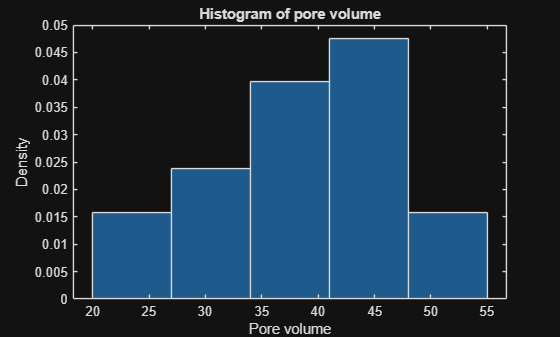

porevolume = readvars('data\porevolume.txt');
n = length(porevolume);

numberBins = ceil(sqrt(n));

histogram(porevolume, numberBins, 'Normalization', 'pdf')
xlabel('Pore volume')
ylabel('Density')
title('Histogram of pore volume')

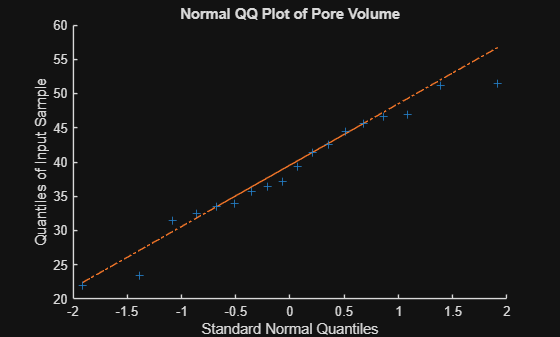


qqplot(porevolume)
title('Normal QQ Plot of Pore Volume')

We previously generated the defauly 95% confidence interval. Let's examine a different confidence level. 

confidence = 0.98;
alpha = 1 - confidence;
criticalQuantile = 1 - alpha / 2

criticalQuantile = 0.9900


[~, ~, ci] = ttest(porevolume, mean(porevolume), "Alpha", alpha)

ci =    33.5345
   43.7877


## Exercise 4

% Reset seed to default
rng("default")

% Define array dimensions
sampleSize = 36;
nSamples = 500;

% Define model parameters
mu = 20;
sigma = 5;

% Generate samples
samples = normrnd(mu, sigma, sampleSize, nSamples);

% Compute sample statistics
sampleAverage = mean(samples);
sampleStd = std(samples);

% Set confidence level
confidence = 0.95;
alpha = 1 - confidence;
criticalQuantile = 1 - alpha / 2;

% Define margin of error for each distribution
marginNormal = norminv(criticalQuantile) * sigma / sqrt(sampleSize); % this is a single number
marginT = tinv(criticalQuantile, sampleSize - 1) * sampleStd / sqrt(sampleSize); % this is a vector

% Calculate confidence intervals for the normal and t-distribution
ciNormal = [sampleAverage - marginNormal;
    sampleAverage + marginNormal]

ciNormal =    20.1603   18.5900   18.1205   17.8666   17.4030   18.4787   17.6449   18.8027   17.3223   17.9048   18.0727   18.5598   17.6513   19.2135   17.9070   19.5136   19.0539   17.3758   18.3762   17.5948   16.8737   18.3257   17.6833   17.0799   17.2916   18.0460   19.4048   19.1707   19.2265   19.3836   17.0213   19.9400   19.3220   17.3732   19.5973   21.3200   18.9377   17.9413   18.9893   17.8111   17.4550   17.4681   18.9958   18.1069   17.5638   19.0967   17.6725   19.4443   17.9552   17.9145
   23.4269   21.8566   21.3871   21.1333   20.6696   21.7454   20.9115   22.0693   20.5889   21.1715   21.3393   21.8264   20.9179   22.4801   21.1736   22.7803   22.3205   20.6424   21.6428   20.8614   20.1403   21.5923   20.9499   20.3465   20.5582   21.3126   22.6714   22.4373   22.4931   22.6502   20.2879   23.2066   22.5887   20.6399   22.8639   24.5866   22.2043   21.2079   22.2559   21.0777   20.7216   20.7347   22.2624   21.3735   20.8304   22.3634   20.9391   22.7109   21.22

ciT = [sampleAverage - marginT;
    sampleAverage + marginT]

ciT =    19.4328   18.5910   18.1164   17.5237   17.3056   18.8091   17.6586   18.7516   17.1580   17.7496   18.1350   18.7570   17.5539   19.6818   17.6367   19.6434   19.2550   17.3236   18.2335   17.8028   16.6898   18.2512   17.8413   16.9876   17.0628   18.1360   19.4923   18.8422   18.7615   19.5701   16.7647   20.1037   19.2071   17.0645   19.9170   21.1805   19.3425   17.8515   19.1937   17.5948   17.7018   17.1780   18.7704   18.0039   17.7690   18.8625   17.7936   19.3122   17.8957   17.7937
   24.1544   21.8555   21.3913   21.4762   20.7669   21.4150   20.8978   22.1203   20.7531   21.3267   21.2771   21.6291   21.0153   22.0117   21.4439   22.6505   22.1194   20.6947   21.7856   20.6534   20.3242   21.6668   20.7919   20.4388   20.7870   21.2226   22.5839   22.7658   22.9582   22.4637   20.5446   23.0429   22.7037   20.9486   22.5442   24.7261   21.7996   21.2977   22.0515   21.2941   20.4749   21.0248   22.4878   21.4765   20.6252   22.5976   20.8179   22.8430   21.2814   


% Compute proportion of times the population mean is contained in the
% samples
sum(mu >= ciNormal(1, :) & mu <= ciNormal(2, :)) / nSamples

ans = 0.9640

sum(mu >= ciT(1, :) & mu <= ciT(2, :)) / nSamples

ans = 0.9680